# Assignment 1

## 1 The assignment

New job. YEAH! After you got your first cup of coffee, some dude comes up to you and asks for your expertise in DSP. Rumours spread quickly that you graduated from DTU and that you kick a**. You colleague hands you a (pretty worn) piece of paper where you see a plot. That plot shown on the y-axis "Magnitude (a.u., dB)" and on the x-axis "Frequency (Hz)". You can see that there is a peak around 1000 Hz and some minor peaks around that - and the paper is gone beyond 3000 Hz, so you don't know where the plot ends. You can also identify that the individual samples are 2 Hz apart from each other. Asking about the origin of the signal, the reply is, that it is a recording of someone singing a 1000 Hz tone ("/iiiiiiiiiiii/", recorded with some "standard" equipment (whatever that means). The colleague REALLY wants to improve DSP skills and asks for your help. Prepare an overview sheet where you show 

a) a "clean" 1000 Hz signal, together with a recording of you "singing" that signal, and 

b) a reproduction of that plot you got handed out - meaning a magni- tude spectrum of the two plotted signals that is in accordance with what you see on the original paper. Name all the properties that you can deduce from the orginal plot and what your colleague needs to be aware of if he/she/they want to reproduce your plot. Finally, you also tell them what they need to do in the hardware-group in order to reproduce that recorded signal through headphones.

From the graph, it is seen that we have frequency along the x-axis and magnitude along the y-axis. From this it could be a Fourier transform of someone signing "iiiiiii". 

In the frequency domain, the spacing of 2Hz between frequencies should be the spectral resolution.

To recreate this, i assume "standard equipment", means a sampling frequency of 44100Hz, as this is pretty standard when recording audio.

Using the spectral resolution and the samping frequency the duration of the clip/amount of samples can be deduced

clear all;
n_samples = 44100/2

n_samples = 22050

duration = 1/2

duration = 0.5000

Firstly, to get an idea of the original signal, i will try to whistle a note at 500Hz and compare that with a clean 500Hz sine wave.

file = 'assignment1/sing_500Hz.wav';
[x, fs_x] = audioread(file);

x = x(1:22050); % Ensure correct number of samples - prints error if too short
x = x; % Normalize the recording

First off, the function of sine is generated, where the amplitude is scaled to approximately match the amplitude of the recorded signal.

t = 0: 1/fs_x: length(x)/fs_x - 1/fs_x;
f_sin = 500;    %1kHz
offset = 1.5;   %making the simulation & recording match up
x_sin = sin(2*pi*f_sin*t + offset);
[n, i] = max(x);
peak = t(i);    % finding the greatest value, where the sinusoids match the best

From this, the two are overlapped in a plot, where a couple of periods of the sinosoids are shown.

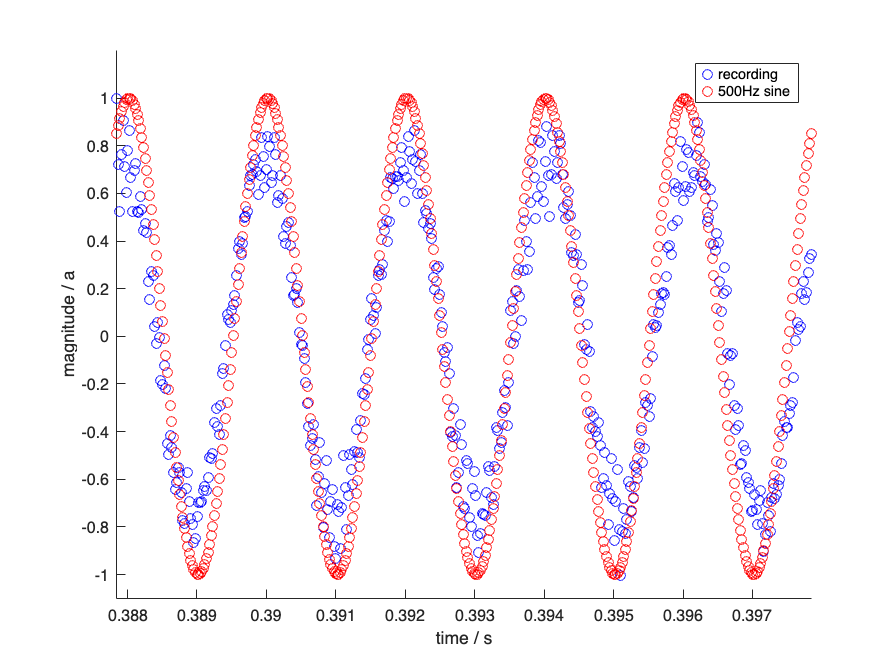

%Comparing 5 periods of the whistle and sinusoid
n = 5;  %amound of periods
period = n * 1/f_sin;


%x limits
xmax = period + peak;
xmin = peak;

figure(1)
hold on;
plot(t, 1/max(x) * x, 'bo')     %plot of normalized recording
plot(t, x_sin, 'ro')
xlim([xmin, xmax])
ylim([-1.1, 1.2])               %Matlab autoscale didn't look pretty
legend('recording', [num2str(f_sin), 'Hz sine'])
xlabel('time / s')
ylabel('magnitude / a')

From this, the sinusoids look like they match up, with varying amplitude for the recorded signal, but let's see what it looks like in the frequency domain!

Using the fourier transform, and then making the amplitude in dB, to match the ruined piece of paper i was given.

[Y, freq] = make_spectrum(x, fs_x);
[Sine, ~] = make_spectrum(x_sin', fs_x);

Y_db = 20*log10(abs(Y));
Sine_db = max(0, 20*log10(abs(Sine)));


Now that both arrays are created, overlapping plots can be made to visualize both signals in the frequency domain.

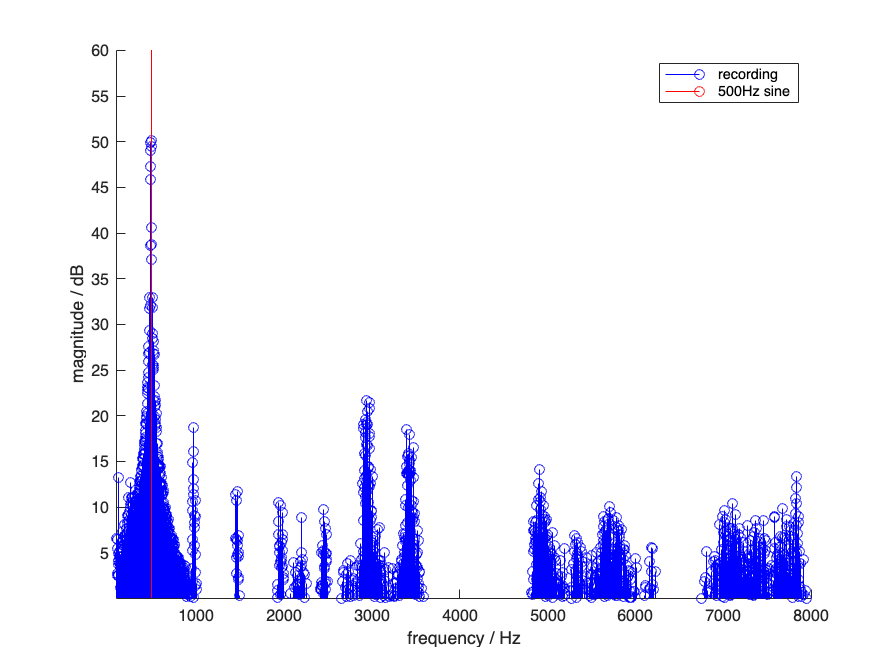

%x limits of human vocal range
xmax = 8000;
xmin = 100;

%Plot of the fourier domain
figure(2)
hold on;
stem(freq, Y_db, 'b')
stem(freq, Sine_db, 'r')
xlim([xmin, xmax])
ylim([0.01, 60])
legend('recording', [num2str(f_sin), 'Hz sine'])
xlabel('frequency / Hz')
ylabel('magnitude / dB')

Which is really cool, as the created sine wave at 500Hz only contains a single frequency, it will also only show a single value in the frequency domain. While the recorded signal shows a bunch of frequencies, with smaller magnitudes, around 1kHz. 

This makes a ton of sense, since a human can't cleanly replicate a single frequency. Additionaly both noise from the background and microphone will create clutter - as this has not been filtered in the recorded sample.

%% Play the recorded audio
%clear sound;
%sound(x, fs_x);